% 清除命令窗口和变量  
clc  
clear  
  
% 定义两种玻璃的名称  
glass={'H-K9L','CAF2','SF2','SK-1310'};  
  
% 定义波长（单位为毫米）  
waveLength=640e-6; %波长/mm  
glassCatPath='C:\Users\M1CKEY\Documents\Zemax\Glasscat';
% 调用函数计算玻璃在特定波长下的折射率  
% 'C:\Users\M1CKEY\Documents\Zemax\Glasscat' 是玻璃折射率数据库的路径  
n=calGlassRI(glass,waveLength,glassCatPath);  
  
% 显示计算得到的折射率  
disp(n)

    1.5148
    1.4328
    1.6432
    1.4570



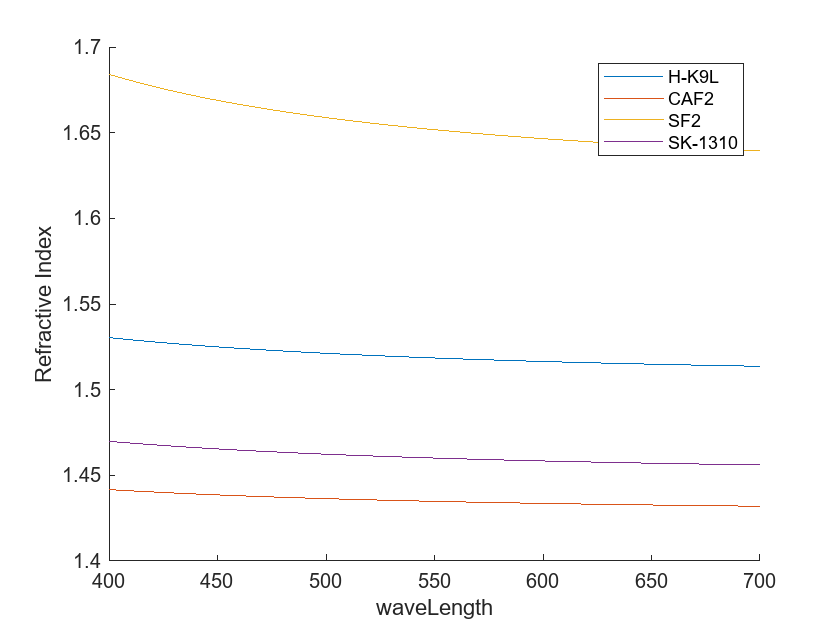

  
% 创建一个波长范围从400nm到700nm的线性空间，共1000个点  
waveLength=linspace(400e-6,700e-6,1000);  
  
% 调用函数计算玻璃在整个波长范围内的折射率  
n=calGlassRI(glass,waveLength,glassCatPath);  
  
% 绘制两种玻璃的折射率与波长的关系曲线  
% n(1,:) 表示第一种玻璃的所有波长下的折射率  
% n(2,:) 表示第二种玻璃的所有波长下的折射率  
% waveLength*1e6 将波长从毫米转换为纳米，以进行绘图  
figure 
hold on
for ii=1:size(n,1)
plot(waveLength*1e6,n(ii,:))  
end
% 为两条曲线添加图例  
legend(glass)  
  
% 设置x轴标签  
xlabel('waveLength')  
  
% 设置y轴标签  
ylabel('Refractive Index')